### **Método do Ponto Fixo****  (MPF)**


$$x^{k+1} = \Phi(x^{k})$$


onde $\Phi$ é nossa função de iteração de ponto fixo. 

Vamos encontrar o zero da função $f(x) = -0.5x^{2}+2.5x+4.5$ no intervalo de $[-2.5,0]$utilizando o MPF, com $\Phi_{1}(x) = \frac{0.5x^{2}-4.5}{2.5}$ e $\Phi_{2}(x) =\sqrt{ \frac{-2.5x-4.5}{2.5}}$, da  com erro relativo igual ou menor que $10^{-4}$. Uso o chute inicial $x^{0} = -1$.

**Graficamente, **

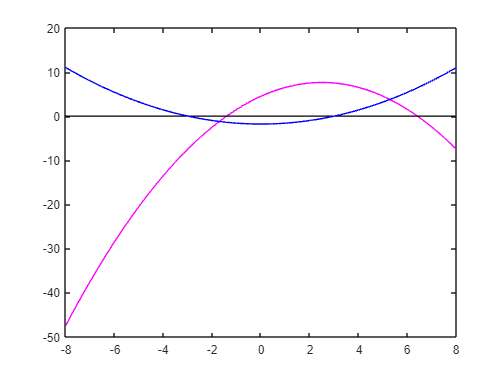

x= -8:0.01:8;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
phi1 = fun_iteracao(x);
plot(x,phi1, 'blue')
hold off

**Implementação do MPF:**

format long
x0 = -1;
tol = 10^-4;
k = 0;
erro_relativo = 10;

while erro_relativo > tol
    k = k+1;
    x = fun_iteracao(x0);
    xk(k, :) = x0;
    fk(k, :) = fun(x0);
    erro_relativo = abs(x - x0)/abs(x);
    x0 = x;
end
[xk, fk]

ans =   -1.000000000000000   1.500000000000000
  -1.600000000000000  -0.780000000000000
  -1.288000000000000   0.450528000000000
  -1.468211200000000  -0.248350063902720
  -1.368871174438912   0.140917917797837
  -1.425238341558047  -0.078748019018682
  -1.393739133950574   0.044397778370918
  -1.411498245298941  -0.024909261488347
  -1.401534540703602   0.014014113848366
  -1.407140186242949  -0.007872217477292


fprintf("O valor da aproximação para X é %d -> O número de iterações é %d", x, k)

O valor da aproximação para X é -1.405089e+00 -> O número de iterações é 16

**Definindo as funções que serão utilizadas:**

function f1 = fun(x)
    f1 = -0.5*x.^2 +2.5*x + 4.5;
end
function g1 = fun_iteracao(x)
    g1 = (0.5*x.^2 - 4.5)/2.5;
end